# Kondition der Lagrange-Polynominterpolationsaufgabe

Wir betrachten die Lagrange-Interpolationsaufgabe auf dem Intervall $[0,1]$, mit Daten

          
$$f(x_j)=3 \sin(3 x_j), \quad x_j \in [0,1], \quad j=0,\ldots,n.$$


Das Interpolationspolynom wird in der Lagrange-Basis

        
$$P(f|x_0,\ldots,x_n)(x)= \sum_{j=0}^n 
f(x_j) \ell_{jn}(x)$$


dargestellt (siehe Buch).  Für die Stützstellen $x_j$ untersuchen  wir zwei Varianten: eine äquidistante Verteilung der Stützstellen und die sogenannten Tschebyscheff-Stützstellen (siehe Buch).

n=12 % Polynomgrad

n = 12

[EqKnoten,TschKnoten]=Stuetzstellen(n); % n+1 Stützstellen werden bestimmt

Wir betrachten fehlerbehaftete Daten $\tilde f(x_j)=f(x_j)(1+\delta \ast r_j)$, mit $r_j$ die Realisierung einer auf $[-1,1]$ gleichverteilten  Zufallsvariable, und $\delta \geq 0$ ein Parameter, der die relative Größe der Datenstörung kontrolliert.  

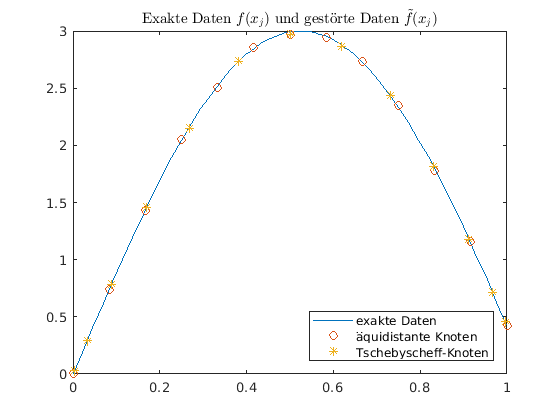

delta=0.01;
[EqDaten,TschDaten]=Daten(EqKnoten,TschKnoten,delta); % gestörte Daten werden erzeugt
fplot(@(x) 3*sin(3*x),[0,1]);
hold on;
plot(EqKnoten,EqDaten,'o');
plot(TschKnoten,TschDaten,'*');
legend('exakte Daten','äquidistante Knoten','Tschebyscheff-Knoten','Location','SouthEast');
title('Exakte Daten $f(x_j)$ und gest\"{o}rte Daten $\tilde f(x_j)$','Interpreter','latex');
hold off;

Die Lagrange-Interploationspolynome zu den (gestörten) Daten  werden geplottet.

# Aktivität:

Variieren Sie, für festes $n\in \{4,8,12,16\}$, den $\delta$-Wert, z.B. $\delta \in \{0,0.01, 0.05,0.1\}$ und beobachten Sie die Effekte der Datenstörung auf die entsprechenden Lagrange-Interpolationspolynome.

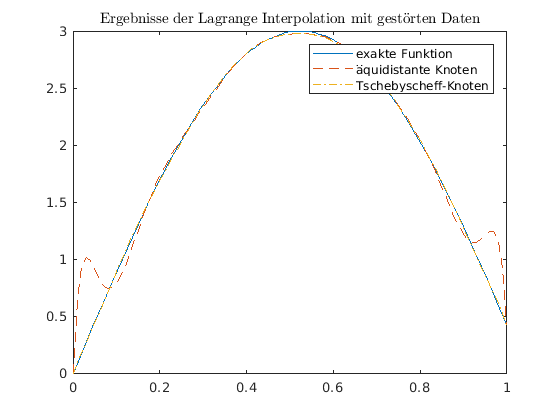

figure(2)
mplot=101; % Anzahl Gitterpunkte für plot
x=linspace(0,1,mplot);
PolynomEq=zeros(mplot,1);
PolynomTsch=zeros(mplot,1);
for i=1:mplot
    PolynomEq(i)=  lagrange(x(i),EqKnoten,EqDaten);
    PolynomTsch(i)=lagrange(x(i),TschKnoten,TschDaten);
end
fplot(@(x) 3*sin(3*x),[0,1]);
hold on;
plot(x,PolynomEq,'--');
plot(x,PolynomTsch,'-.');
legend('exakte Funktion','äquidistante Knoten','Tschebyscheff-Knoten');
title('Ergebnisse der Lagrange Interpolation mit gest\"{o}rten Daten','Interpreter','latex');
hold off;

function [eqKnoten,TschKnoten]=Stuetzstellen(n)
h=1/n;
eqKnoten=zeros(n+1,1);
TschKnoten=zeros(n+1,1);
for i=0:n
    eqKnoten(i+1)=i*h;
    TschKnoten(i+1)=0.5-0.5*cos(pi*(2*i+1)/(2*n+2));
end
end

function [eqDaten,TschDaten]=Daten(eqKnoten,TschKnoten,delta)
m=length(eqKnoten);
eqDaten=zeros(m,1);
TschDaten=zeros(m,1);
r = -1 + 2.*rand(m,1);
for i=1:m
    eqDaten(i)=3*sin(3*eqKnoten(i))*(1+delta*r(i));
    TschDaten(i)=3*sin(3*TschKnoten(i))*(1+delta*r(i));
end
end

function y=lagrange(x,Knoten,Daten)
% Diese Funktion wertet das Interpolationspolynom in der Lagrange-Darstellung an der Stelle x aus.
    m=length(Knoten);
    L=ones(m,1);
    for i=1:m
        for k=1:m
            if (i~=k)
                L(i)=L(i)*(x-Knoten(k))/(Knoten(i)-Knoten(k));
            end
        end
    end
    y=Daten'*L;
end
 